# Zadanie 5 - Pole elektryczne i charakterystyka pojemnościowo napięciowa dla danych zmierzonych dla złącza Schottky'ego na krzemie typu p

[file,path]=uigetfile('*.dat');
if file==0
    disp('User selected Cancel')
else 
    disp(['User selected',fullfile(path,file)])
end

User selectedF:\nauka\pwr\rok 3 semestr 6(letni)\Metody Symulacji Fotoogniw - Labolatorium\CV.dat



cd(path);
fileID=fopen(file);
data=textscan(fileID,'%f%f',"HeaderLines",2);
U=data{1};%[V]
C=data{2};%[F]
temp=190;%[K]
A=2.01;%%[mm^2]
q=1.602e-19;%%[C]
k=1.381e-23;%[J/K]
epsilon_0=8.854187817e-12;%%[F/m]
epsilon_r=11.68;
epsilon=epsilon_r*epsilon_0;%%[F/m=A^2*s^4/(kg*m^3)]
C=C';
U=U';

## Charakterystyka pojemnościowo-napięciowa:

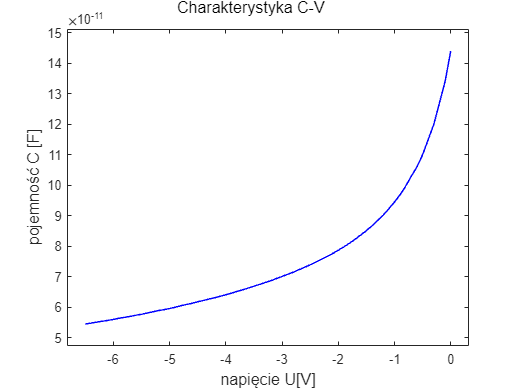


plot(U,C,'color','blue','Linewidth',1.1)
zak_U=max(abs(U));
xlim([-zak_U*1.05,zak_U*0.05]);
zak_C=max(abs(C));
ylim([min(C)-zak_C*0.05,zak_C*1.05]);
xlabel("napięcie U[V]","FontSize",12);
ylabel("pojemność C [F]","FontSize",12);
text(-zak_U*0.75, zak_C*1.1,'Charakterystyka C-V','FontSize', 12);

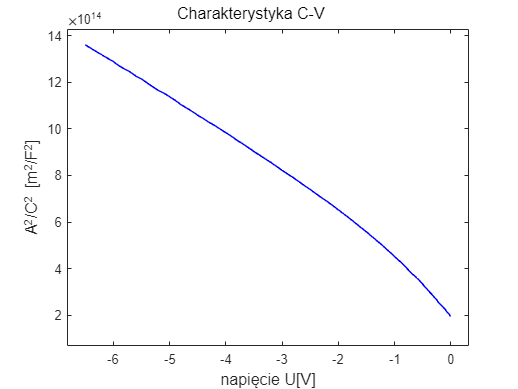


A2C2=A.^2./C.^2*1.0e-6;
%disp(A2C2)
plot(U,A2C2,'color','blue','Linewidth',1.1)
zak_U=max(abs(U));
xlim([-zak_U*1.05,zak_U*0.05]);
zak_A2C2=max(abs(A2C2));
ylim([zak_A2C2*0.05,zak_A2C2*1.05]);
xlabel("napięcie U[V]","FontSize",12);
ylabel("A^{2}/C^{2} [m^2/F^2]","FontSize",12);
text(-zak_U*0.75, zak_A2C2*1.1,'Charakterystyka C-V','FontSize', 12);


len=size(C);
dCdV=zeros(1,len(2));     %to bawienie sie z rozmiarami, i ze kazda
dCdV_back=zeros(1,len(2));% zmienna to macierz , strasznie mnie meczy i boli
dCdV_m=zeros(1,len(2));

dCdV(1,1)=(C(1,2)-C(1,1))/(U(1,2)-U(1,1));
for i=2:len(2)-1
    dCdV(1,i)=(C(1,i+1)-C(1,i))/(U(1,i+1)-U(1,i));
    dCdV_back(1,i)=(C(1,i)-C(1,i-1))/(U(1,i)-U(1,i-1));
    dCdV_m(1,i)=(C(1,i+1)-C(1,i-1))/(U(1,i+1)-U(1,i-1));
end    
dCdV_back(1,len(2))=(C(1,len(2))-C(1,len(2)-1))/(U(1,len(2))-U(1,len(2)-1));
dCdV_back(1,1)=dCdV(1,1);
dCdV(1,len(2))=dCdV_back(1,len(2));
dCdV_m(1,1)=dCdV(1,1);
dCdV_m(1,len(2))=dCdV_back(1,len(2));
%dCdV_m=smoothdata(dCdV_m);

Można zwrócić uwagę na wykres A^2/C^2 od U, widać , że funkcja ta nie zachowuje się liniowo i nia da się jednoznacznie określić z interpolacji ile wynosi U zerujące - czyli nie zanmy tutaj Vbi. Oznacza to ,że to złącze nie zachowuje się jak kondensator płaski.

## Pochodne i ich porównanie:

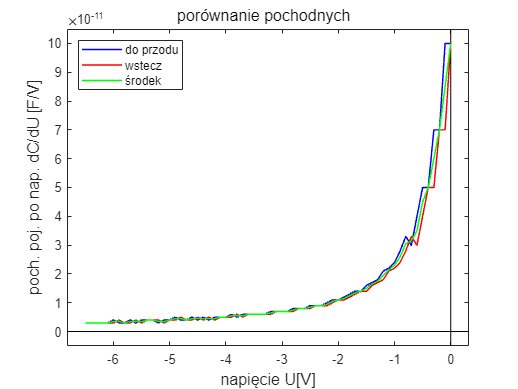


zak_U=max(abs(U));
zak_DC=max(abs(dCdV_back));
plot(U,dCdV,'color','blue','Linewidth',1.1)
xlim([-zak_U*1.05,zak_U*0.05]);
hold on
plot([-zak_U*1.05,zak_U*0.05], [0 0], 'Color', 'k');
plot([0 0], [-zak_DC*0.05,zak_DC*1.05], 'Color', 'k');
plot(U,dCdV_back,'color','red','Linewidth',1.1)
plot(U,dCdV_m,'color','green','Linewidth',1.1)
xlim([-zak_U*1.05,zak_U*0.05]);
ylim([-zak_DC*0.05,zak_DC*1.05]);
xlabel("napięcie U[V]","FontSize",12);
ylabel("poch. poj. po nap. dC/dU [F/V]","FontSize",12);
text(-zak_U*0.75, zak_DC*1.1,'porównanie pochodnych','FontSize', 12);
legend("do przodu","","","wstecz","środek","Location","northwest");
hold off

Widać z wykresu, że najlepsze wyniki daje pochodna metodą centralną. Niestety koniec i początek dla tej metody nie jest liczony, co oznacza,że dla pierwszego i ostatniego punktu trzeba powtórzyć poprzedni wynik lub wziąć wartości z innej metody.

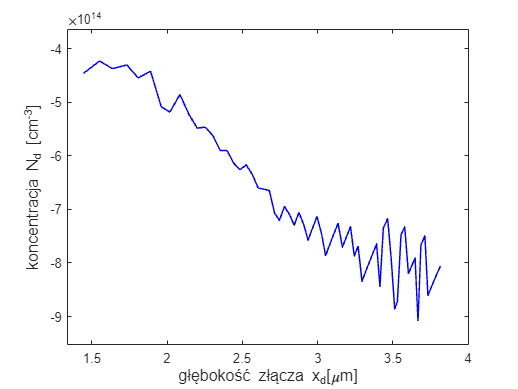

x_d=A*epsilon./C;%[mm^2*F/m/F=1e-6m^2*F/m/F=1e-6m=um]
N_d=-C.^3/A^2/epsilon/q./dCdV_m*1.0e6;%[F^3/mm^4/(F/m)/C/(F/V)=cm^-3*10e6]
x_d=flip(x_d);
N_d=flip(N_d);


plot(x_d,N_d,'color','blue','Linewidth',1.1)
zak_xd=max(abs(x_d));
xlim([zak_xd*0.35,zak_xd*1.05]);
zak_N=max(abs(N_d));
ylim([-zak_N*1.05,-zak_N*0.4]);
xlabel("głębokość złącza x_d[\mum]","FontSize",12);
ylabel("koncentracja N_d [cm^{-3}]","FontSize",12);

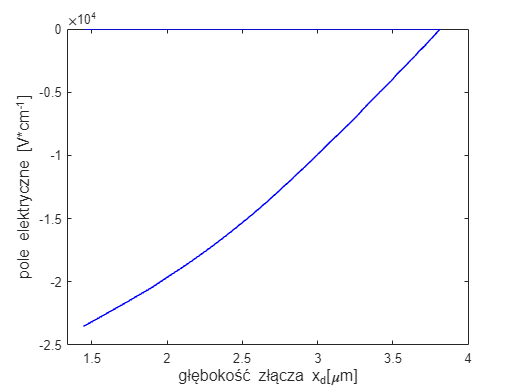

%smoothed_data = smoothdata(N_d);
%plot(x_d,-smoothed_data);

%Nc=6.2e15*temp^(3/2);
%Nv = 3.5e15*temp^(3/2);
%Eg=1.12;%%[eV]
%n_i=sqrt(Nc*Nv)*exp(-Eg*q/(2*k*temp));%%[cm^-3]
%V_bi=2*log(Nd/n_i)*k*300/q;%%[V]


rho=-q*N_d;% [C*cm^-3]
E_el=zeros(size(x_d,2));
for i=size(x_d,2):-1:2
    E_el(i-1)=E_el(i)+rho(i)/epsilon*(x_d(i-1)-x_d(i))/100;%[cm^-3*C*um*kgm^3/A^2/s^4=V/cm*10^-2]
end  

plot(x_d,E_el,'color','blue','Linewidth',1.1)
zak_E=max(abs(E_el));
xlim([zak_xd*0.35,zak_xd*1.05]);
zak_N=max(abs(N_d));
%ylim([zak_E*0.4,zak_E*1.05]);
xlabel("głębokość złącza x_d[\mum]","FontSize",12);
ylabel("pole elektryczne [V*cm^{-1}]","FontSize",12);

Wyniki są spójne do pewnego stopnia. Rzędowo otrzymano podobne wyniki jak w rozw. obszar. całk. zuboż. Niestey mały zakres zbadanych wartości nie pozwolił na jednoznaczne wyznaczenie granicy spadku koncentracji nośników, przez to nie wiadmo czy koncentracja będzie rosła dalej (co oznacza całkowicie złą zależność koncentracji od głębokości w porównaiu do rozw. obszar. całk. zuboż. - odchodząc od 0 powinna malec), Skutkiem tego jest także, że pole elektryczne ma poprawną monotoniczność, to jego charakterystyka jest mocno narzucona warunkami brzegowymi. Te zadano jedynie kierując się tym, że pole powinno schodzić do 0 dla końca złącza.

## Źródła:

[1] Instytut Fizyko Techniczny imienia A. F. Ioffego Rosyjskiej Akademii Nauk w Petersburgu

http://www.ioffe.ru/SVA/NSM/Semicond/Si